audiofilereader = dsp.AudioFileReader('guitartune.wav', ...
    'SamplesPerFrame',44100);
x = audiofilereader();
SAaudio = dsp.SpectrumAnalyzer( ...
    'SampleRate',44100, ...
    'ShowLegend',true, ...
    'Title','Audio Signal', ...
    'ChannelNames',{'Input signal' 'Demodulated signal'});
SAfm = dsp.SpectrumAnalyzer( ...
    'SampleRate',152e3, ...
    'Title','FM Broadcast Signal');
fmbMod = comm.FMBroadcastModulator( ...
    'AudioSampleRate',audiofilereader.SampleRate, ...
    'SampleRate',200e3);
fmbDemod = comm.FMBroadcastDemodulator(fmbMod)

fmbDemod =   comm.FMBroadcastDemodulator with properties:

            SampleRate: 200000
    FrequencyDeviation: 75000
    FilterTimeConstant: 7.5000e-05
       AudioSampleRate: 44100
             PlaySound: false
                Stereo: false
                  RBDS: false


info(fmbMod)

ans = struct with fields:
       AudioDecimationFactor: 441
    AudioInterpolationFactor: 2000
        RBDSDecimationFactor: 19
     RBDSInterpolationFactor: 320


info(fmbDemod)

ans = struct with fields:
       AudioDecimationFactor: 50
    AudioInterpolationFactor: 57
        RBDSDecimationFactor: 50
     RBDSInterpolationFactor: 57


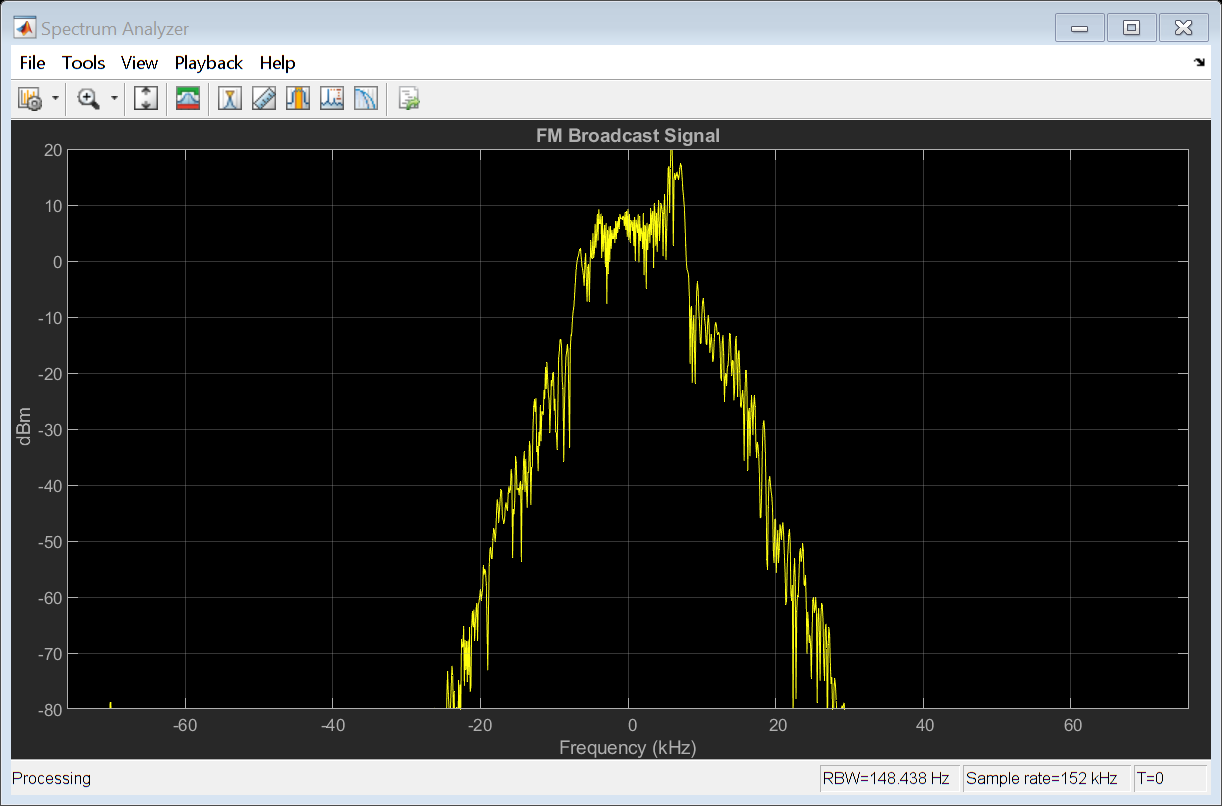

y = fmbMod(x);
SAfm(y)

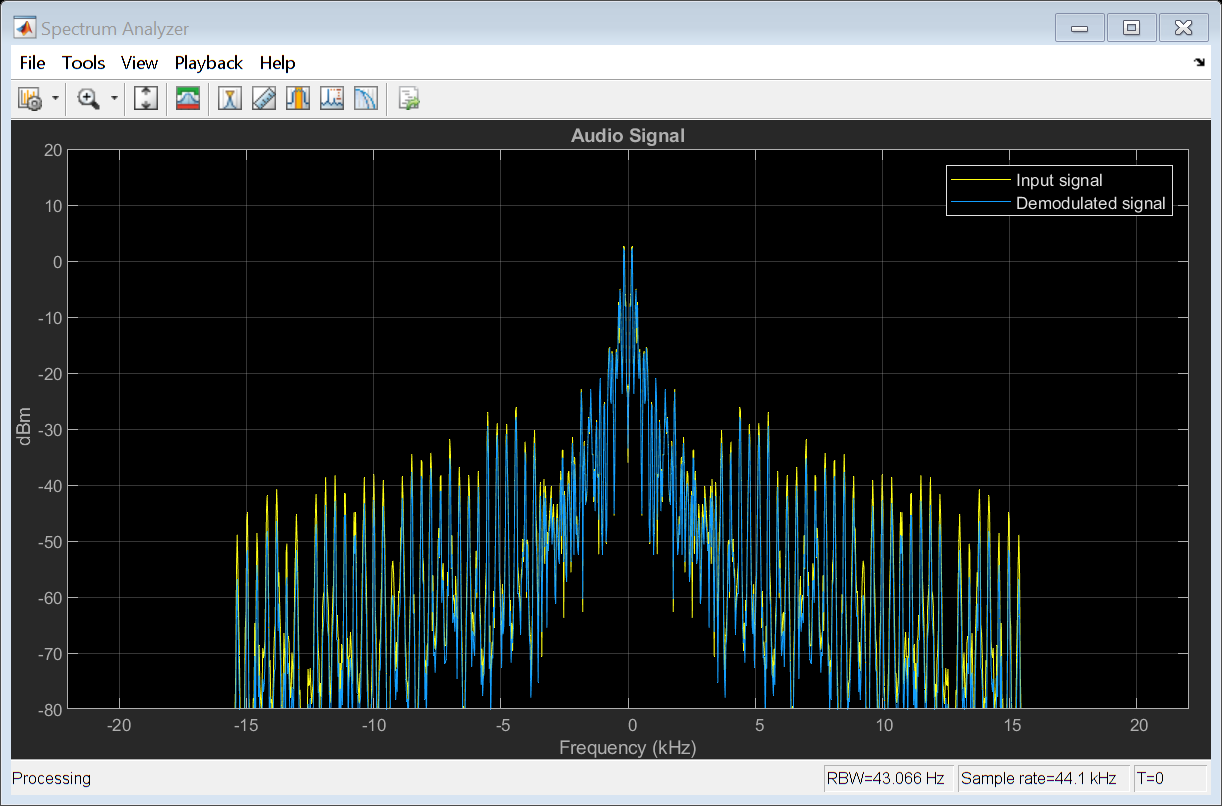

z = fmbDemod(y);
SAaudio([x z])